# Array Mutual Coupling

This notebook provides a detailed implementation and analysis of mutual coupling effects in an arbitrary array configuration composed of Log-Periodic Dipole Antenna (LPDA) elements. The simulation evaluates key performance metrics, including:

- Coupling matrix

- Reflected power

- Voltage Standing Wave Ratio (VSWR)

- Beam pattern distortion due to coupling

The analysis builds upon the array configuration defined in the `ArbitraryArrayBeamforming.mlx` notebook and extends it to include the electromagnetic interactions between array elements.

### Construct Array Geometry Model

The initial simulation setup defines key physical and signal parameters for the antenna array system, including frequency, element spacing, and angular resolution.

%% Simulation Parameters
c = physconst('LightSpeed');           % Speed of light [m/s]
fc = 25e6;                             % Center frequency [Hz]
lambda = c / fc;                       % Wavelength [m]
kc = 2*pi/lambda;                      % Wave number [rad/m]

nElem = 16;                            % Number of antenna elements
dElem = 0.55 * lambda;                 % Inter-element spacing [m]

K = 1000;                              % Number of angular samples (fidelity)
azAngles = linspace(-pi/2, pi/2, K).'; % Azimuth scan angles [rad]
elAngles = linspace(-pi/2, pi/2, K).'; % Elevation scan angles [rad]

The LPDA element is modeled using the center frequency to define its physical dimensions. The geometry includes board size, feed line, and arm configuration. This configuration results in a broadband, directional antenna optimized for operation at 25 MHz.

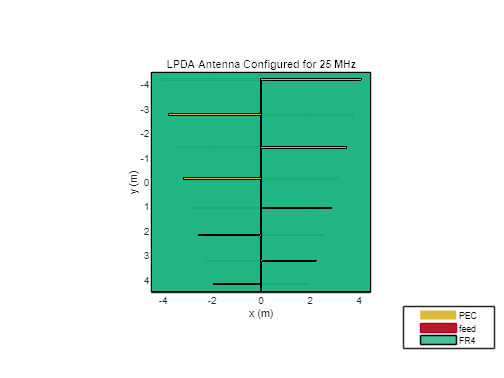

% Define LPDA element structure
element = lpda;
element.BoardLength = 0.75 * lambda;
element.BoardWidth  = 0.75 * lambda;
element.Height      = 0.01 * lambda;
element.StripLineWidth = 0.005 * lambda;
element.FeedLength     = 0.025 * lambda;

% Define LPDA arm configuration
nArms = 8;
armStart = 0.16 * lambda;
armEnd   = 0.34 * lambda;
element.ArmLength  = linspace(armStart, armEnd, nArms);
element.ArmWidth   = 0.02 * element.ArmLength;
element.ArmSpacing = linspace(0.08, 0.12, nArms-1) * lambda;

% Orient the LPDA element by tilting along the y-axis
element.TiltAxis = [0 1 0; 1 1 0];
element.Tilt     = [180 180];

% Visualize the single antenna element
figure("Name", "Single Element Geometry");
show(element);
title("LPDA Antenna Configured for 25 MHz");
axis equal;
grid on;
view(0, 270);

The LPDA element is replicated to form a uniform linear array (ULA) along the x-axis. All elements are positioned symmetrically about the array’s center.

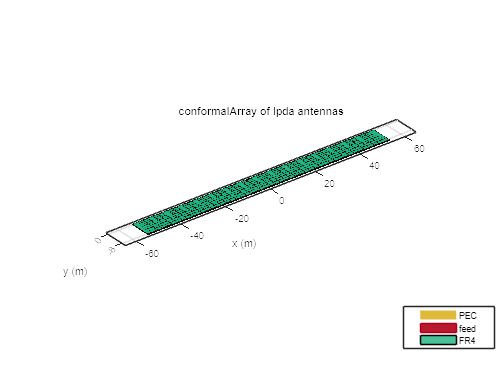

% Define array cartesian coordinates
elementXPositions = dElem * ((0: nElem-1) - (nElem-1)/2).';
elementYPositions = zeros(nElem, 1);
elementZPositions = zeros(nElem, 1);

% Generate confromal array geometry
array = conformalArray;
array.Element = element;
array.ElementPosition = [elementXPositions, elementYPositions, elementZPositions];

% Plot 3-dimensional array geometry
figure("Name", "Array Geometry");
show(array);

### Load Element Radiation Pattern

To reduce computational overhead, the LPDA element radiation patterns—originally simulated in the `ArbitraryArrayBeamforming.mlx` notebook—are directly imported into the current workspace. These patterns represent the normalized far-field gain response of a single LPDA element in both the azimuth and elevation planes.

% Load pre-computed LPDA radiation pattern
load('patterns/elementPatternAz.mat');

Unrecognized function or variable 'array'.

load('patterns/elementPatternEl.mat');

% % Recompute element patterns if not stored
% elementPatternAz = 10.^(pattern(element, fc, rad2deg(azAngles - pi/2), 0, 'Type', 'gain') / 10).';
% elementPatternEl = 10.^(pattern(element, fc, 0, rad2deg(azAngles - pi/2), 'Type', 'gain') / 10).';

### Compute Coupling Between Elements

In antenna arrays, **mutual coupling** refers to the interaction between elements due to electromagnetic fields, where power transmitted by one element is partially received by its neighbors. This phenomenon alters impedance, current distribution, and ultimately degrades beamforming performance if left unaccounted for.

These interactions are quantitatively described using **S-parameters** (scattering parameters), which relate the **incident** and **reflected** waves at each antenna port. In particular:

- $S_{ii}$ describes reflection at the *i-th* element (return loss).

- $S_{ij}$ represents coupling from element *j* to element *i.*

- The **coupling matrix** is derived from the S-parameter matrix, often combined with the identity matrix to assess active reflection:


$$\mathbf{C} = \mathbf{S} + \mathbf{I}$$


We compute the full S-parameter matrix of the array at the center frequency using MATLAB's electromagnetic solver. The average real impedance across elements is used as the reference load.

% Compute the impedance reference and S-parameters for the array at fc
Z0 = mean(real(impedance(array, fc)));
sObj = sparameters(array, fc, Z0);

% Visualize mutual coupling matrix (S + I)
figure("Name", "Array Mutual Coupling Matrix");
imagesc(db(sObj.Parameters + eye(nElem)));
colorbar;
title("Mutual Coupling Matrix (|S + I| in dB)");
xlabel("Element Index");
ylabel("Element Index");
axis equal tight;
set(gca, 'FontSize', 12, 'FontWeight', 'bold');

We now compute the **active reflection coefficients** across all elements for different azimuth scan angles. These represent how much power is reflected back into each port during beam steering—based on both element mismatch and coupling. The square magnitude of each reflection coefficient represents the fraction of power reflected from each element. We convert this to dB scale and visualize it as a function of azimuth angle.

% % compute active reflected power across elements
% reflectionCeofs = zeros(nElem, K);
% 
% for idx = 1:K
% 
%     % define steering angle and form steering vector
%     azSteer = azAngles(idx);
%     u = [sin(azSteer)*cos(0), cos(azSteer)*cos(0), sin(0)].';
%     svSteer = exp(-1j * kc * (array.ElementPosition * u));
% 
%     % form incident and reflected voltages at each element
%     sIncident = svSteer;
%     sReflected = sObj.Parameters * svSteer;
% 
%     % compute reflection coefficients and store
%     reflectionCeofs(:, idx) = sReflected ./ sIncident;
% 
% end
% 
% % plot reflected power across elements
% reflectionCoefsdB = db(abs(reflectionCeofs).^2);
% figure("Name", "Active Reflected Power Across Array");
% imagesc(elementXPositions/dElem, rad2deg(azAngles), reflectionCoefsdB.');

In practical systems, it's common to set a maximum acceptable reflected power. For example, a VSWR (Voltage Standing Wave Ratio) of 3.0 corresponds to approximately -6 dB reflected power. Elements exceeding this threshold can be flagged or suppressed.

% % compute reflected power against thresold (NO MORE THAN 3dB)
% maxVSWR = 3;
% maxReflect = db(abs((maxVSWR - 1) / (maxVSWR + 1)));
% reflectionCoefsdB(reflectionCoefsdB > maxReflect) = -Inf;
% 
% % plot reflected power against threshold
% figure("Name", "Active Reflected Power Across Array Against Threshold");
% imagesc(elementXPositions/dElem, rad2deg(azAngles), reflectionCeofsdB.');